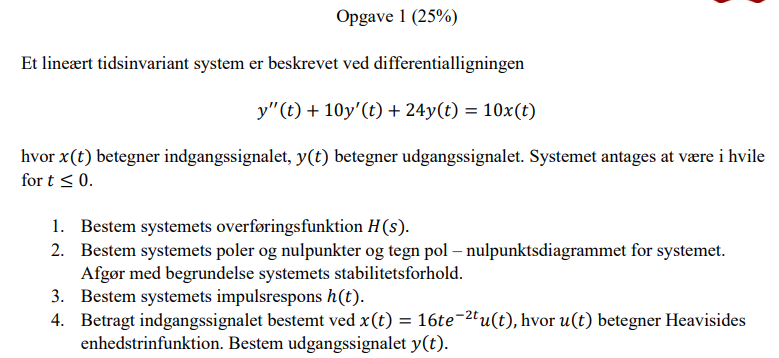

### **1. Bestem systemets overføringsfunktion H(s)**

% Definer nødvendige symbolske variable
syms s t;

% Opgave 1: Bestem systemets overføringsfunktion H(s)
% Koefficienterne for differentialligningen:
% y''(t) + 10y'(t) + 24y(t) = 10x(t)
a = [1, 10, 24];  % Koefficienter for y
b = [10];         % Koefficienter for x

disp('Opgave 1: Overføringsfunktion H(s)');

[num, den, H_forklaring] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);

H_s = poly2sym(num, s) / poly2sym(den, s);
%H_s_str = H_forklaring.resultat;

disp(['H(s) = ', char(H_s)]);

### **2. Bestem poler, nulpunkter og stabilitetsforhold**

disp('Opgave 2: Poler og nulpunkter');
forklaringsOutput = ElektroMatBibTrinvis.analyserDifferentialligningMedForklaring(a);

% Poler:
poler = roots(a);
disp('Poler:');
disp(poler);

% Nulpunkter:
nulpunkter = roots(num);
disp('Nulpunkter:');
disp(nulpunkter);

### **3. Bestem systemets impulsrespons h(t)**

disp('Opgave 3: Impulsrespons h(t)');

[h_t, h_forklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(H_s, s, t);

disp(['h(t) = ', char(h_t)]);

### **4. Bestem udgangssignalet y(t)**

disp('Opgave 4: Udgangssignal y(t)');

% Definer indgangssignalet x(t)
x_t = 16*t*exp(-2*t);

% Beregn Laplace-transformationen af x(t)
X_s = laplace(x_t, t, s);

% Beregn udgangssignalet y(t)
[y_t, y_forklaring] = ElektroMatBibTrinvis.beregnUdgangssignalMedForklaring(H_s, X_s, s, t);
disp(['y(t) = ', char(y_t)]);

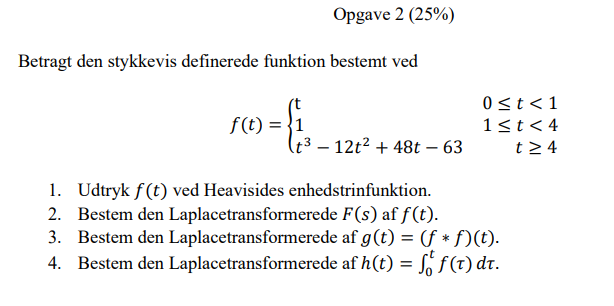

### 1. Udtryk f(t) ved Heavisides enhedstrinfunktion

% Definér symbolske variable
syms t

% Definér de tre stykker af funktionen
f1 = t;             % 0 ≤ t < 1
f2 = 1;             % 1 ≤ t < 4
f3 = t^3 - 12*t^2 + 48*t - 63;  % t ≥ 4

% Definér grænserne for intervallerne
graenser = [0, 1, 4, inf];

% Kald den nye funktion
[f_t, forklaring] = ElektroMatBibTrinvis.stykkevisFunktionMedForklaring({f1, f2, f3}, graenser, t);

% Vis resultatet
disp('f(t) udtrykt med Heavisides enhedstrinfunktion:');
disp(f_t);

### **2. Bestem den Laplacetransformerede F(s) af f(t)**

% Beregn Laplacetransformationen
syms s
[F_s, laplace_forklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(f_t, t, s);
disp('Laplacetransformation F(s):');

F_s_simplify = simplify(F_s);
disp(F_s_simplify);

### **3. Bestem den Laplacetransformerede af g(t) = (f * f)(t)**

% Fra delopgave 2 har vi F(s)
% Brug foldningssætningen: L{f*f} = F(s)·F(s)
[G_s, forklaring3] = ElektroMatBibTrinvis.foldningssaetningMedForklaring(F_s, F_s, s, t);

G_s_simplify = simplify(G_s);
disp(G_s_simplify);

### 4. Bestem den Laplacetransformerede af h(t) = ∫₀ᵗ f(τ) dτ

% Antag at F_s er resultatet fra delopgave 2
syms s

% Anvend integralteoremet: L{∫₀ᵗ f(τ) dτ} = F(s)/s
H_s = F_s / s;

% Simplificér resultatet
H_s = simplify(H_s);

disp('Delopgave 4:');
disp('Laplacetransformationen af h(t) = ∫₀ᵗ f(τ) dτ:');
disp('H(s) = F(s)/s =');
disp(H_s);

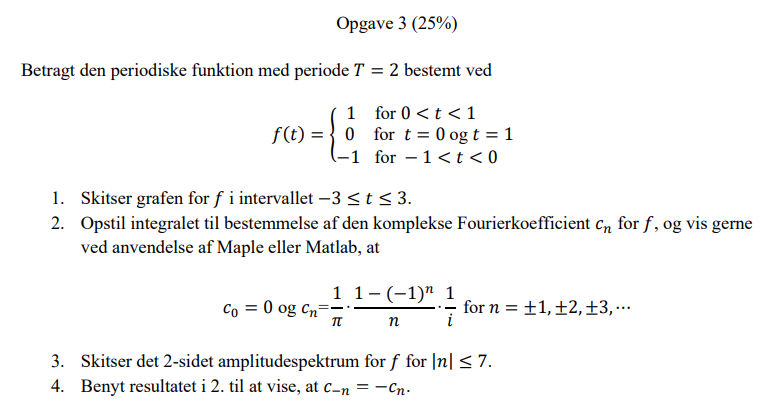

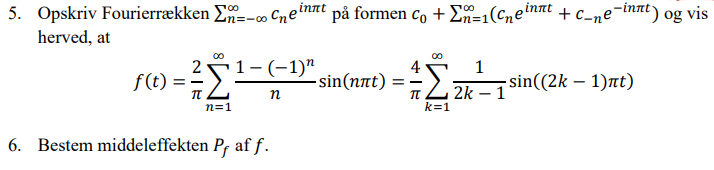

### 1.  Skitser grafen for 𝑓 i intervallet −3 ≤ 𝑡 ≤ 3.

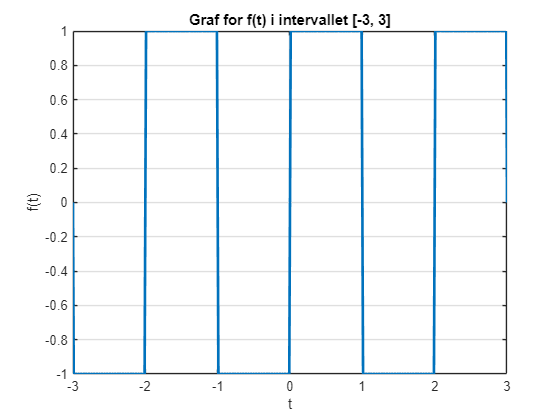

% Evaluer funktionen over flere perioder
t_values = -3:0.01:3;
f_values = zeros(size(t_values));

for i = 1:length(t_values)
    t_mod = mod(t_values(i), 2);
    if t_mod == 0 || t_mod == 1
        f_values(i) = 0;
    elseif t_mod > 0 && t_mod < 1
        f_values(i) = 1;
    else % t_mod > 1 && t_mod < 2
        f_values(i) = -1;
    end
end

% Plot grafen
figure;
plot(t_values, f_values, 'LineWidth', 2);
grid on;
title('Graf for f(t) i intervallet [-3, 3]');
xlabel('t');
ylabel('f(t)');

### 2. Opstil integralet til bestemmelse af den komplekse Fourierkoefficient cn for f , og vis gerne ved anvendelse af Maple eller Matlab, 

===== BEREGNING AF FOURIERKOEFFICIENTER =====
TRIN 1: Identificer den periodiske funktion
Vi starter med den periodiske funktion f(t) med periode T = 2.
   f(t) = piecewise(t in Dom::Interval(0, 1), 1, t == 0 | t == 1, 0, t in Dom::Interval(-1, 0), -1)
 
TRIN 2: Definer grundfrekvensen
Grundfrekvensen beregnes som omega_0 = 2pi/T.
   omega_0 = 2pi/2 = 3.1416 rad/s
 
TRIN 3: Definer formlen for Fourierkoefficienter
Fourierkoefficienten c_n er defineret som:
   c_n = (1/T) * int(f(t) * e^(-jn*omega_0*t) dt) fra -T/2 til T/2
 
TRIN 4: Opsaet integralet
Vi indsaetter funktionen i formlen:
   c_n = (1/2) * int(piecewise(t in Dom::Interval(0, 1), 1, t == 0 | t == 1, 0, t in Dom::Interval(-1, 0), -1) * e^(-jn*3.1416*t) dt) fra -1 til 1
 
TRIN 5: Loes integralet symbolsk
Vi integrerer udtrykket med hensyn til t:
$c_{n}=\frac{{\mathrm{e}}^{-\pi \,n\,1{}\mathrm{i}}\,1{}\mathrm{i}-\mathrm{i}}{2\,

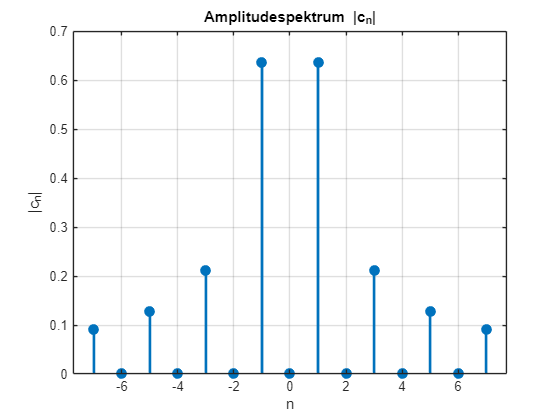

% Definér den periodiske funktion
syms t
T = 2;
% Definer stykkevis funktion
f(t) = piecewise(0<t<1, 1, t==0 | t==1, 0, -1<t<0, -1);

% Beregn Fourier-koefficienter
[cn, forklaringsOutput] = ElektroMatBibTrinvis.fourierKoefficienterMedForklaring(f, t, T);

### 3. Skitser det 2-sidet amplitudespektrum for f for |n|≤ 7.

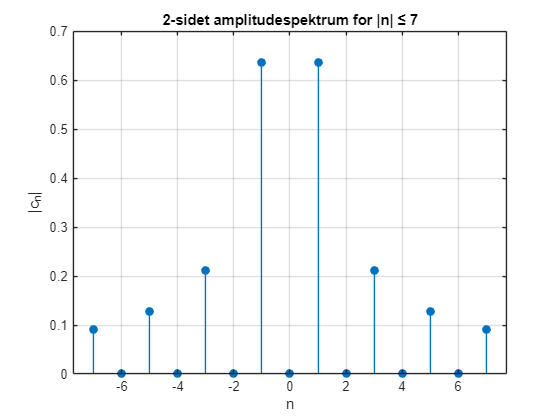

% Vis amplitudespektrum for |n| ≤ 7
n_values = -7:7;
amplitudes = zeros(size(n_values));

for i = 1:length(n_values)
    n = n_values(i);
    if n == 0
        amplitudes(i) = abs(cn.c0);
    elseif n > 0
        amplitudes(i) = abs(cn.(['c' num2str(n)]));
    else
        amplitudes(i) = abs(cn.(['cm' num2str(abs(n))]));
    end
end

figure;
stem(n_values, amplitudes, 'filled');
grid on;
title('2-sidet amplitudespektrum for |n| ≤ 7');
xlabel('n');
ylabel('|c_n|');

### 4. Benyt resultatet i 2. til at vise, at c−n =−cn.

% Bedre verifikation af c_{-n} = -c_n relationen
disp('Verificering af c_{-n} = -c_n:');

Verificering af c_{-n} = -c_n:


for n = 1:7
    c_n = cn.(['c' num2str(n)]);
    c_neg_n = cn.(['cm' num2str(n)]);
    
    disp(['For n = ' num2str(n) ':']);
    disp(['c_' num2str(n) ' = ' num2str(c_n)]);
    disp(['c_-' num2str(n) ' = ' num2str(c_neg_n)]);
    
    % Håndter special-tilfældet hvor begge er (tæt på) nul
    eps = 1e-10;
    if abs(c_n) < eps && abs(c_neg_n) < eps
        disp(['Både c_' num2str(n) ' og c_-' num2str(n) ' er 0 - relationen c_{-n} = -c_n holder (0 = -0)']);
    else
        disp(['Forhold c_-' num2str(n) '/c_' num2str(n) ' = ' num2str(c_neg_n/c_n)]);
    end
    disp(' ');
end

For n = 1:


c_1 = 0-0.63662i


c_-1 = 0+0.63662i


Forhold c_-1/c_1 = -1


For n = 2:


c_2 = 0


c_-2 = 0


Både c_2 og c_-2 er 0 - relationen c_{-n} = -c_n holder (0 = -0)


For n = 3:


c_3 = 0-0.21221i


c_-3 = 0+0.21221i


Forhold c_-3/c_3 = -1


For n = 4:


c_4 = 0


c_-4 = 0


Både c_4 og c_-4 er 0 - relationen c_{-n} = -c_n holder (0 = -0)


For n = 5:


c_5 = 0-0.12732i


c_-5 = 0+0.12732i


Forhold c_-5/c_5 = -1


For n = 6:


c_6 = 0


c_-6 = 0


Både c_6 og c_-6 er 0 - relationen c_{-n} = -c_n holder (0 = -0)


For n = 7:


c_7 = 0-0.090946i


c_-7 = 0+0.090946i


Forhold c_-7/c_7 = -1


### 5. 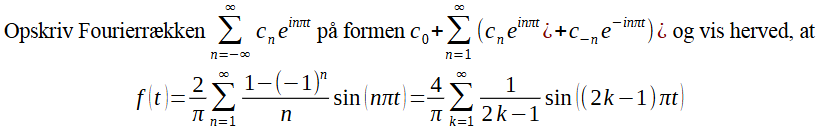

% Omskriv til sinus-række
%N = 20;  % Antal led
%[f_approx, fourierRaekkeOutput] = ElektroMatBibTrinvis.fourierRaekkeMedForklaring(cn, t, T, N);

% Definer funktionen og beregn koefficienter
% Omskriv til trigonometrisk form og identificer mønstre
[series_trig, omskrivningOutput] = ElektroMatBibTrinvis.fourierRaekkeOmskrivningMedForklaring(cn, t, T, 7);

===== OMSKRIVNING AF FOURIERRÆKKE =====
TRIN 1: Definer grundfrekvensen og den generelle Fourierrække
Grundfrekvensen er omega_0 = 2pi/T = 3.1416 rad/s
   Den generelle eksponentielle Fourierrække har formen: f(t) = sum_{n=-oo}^{oo} c_n e^(j n omega_0 t)
 
TRIN 2: Identificer Fourierkoefficienter
Fourierrækken har folgende koefficienter:
$\left(\left(\left(\left(\left(\left(\left(\left(c_{0}=\mathrm{nc}_{1}\,\infty \right)=-1+\mathrm{nc\_}\,1.5707957651346171970720366937891{}\mathrm{i}\right)=-\mathrm{nc}_{3}\,1.5707957651346171970720366937891{}\mathrm{i}\right)=-3+\mathrm{nc\_}\,4.7123798932174716196920930977772{}\mathrm{i}\right)=-\mathrm{nc}_{5}\,4.7123798932174716196920930977772{}\mathrm{i}\right)=-5+\mathrm{nc\_}\,7.8539788256730859853601834689454{}\mathrm{i}\right)=-\mathrm{nc}_{7}\,7.8539788256730859853601834689454{}\mathrm{i}\right)=-7+\mathrm{nc\_}\,10.995535812460141182679831988213{}\mathrm{i}\right)=0.090946{}\mathrm{i}$
 
<

### 6. Bestem middeleffekten P_f af f

% Beregn middeleffekten
[P, effektOutput] = ElektroMatBibTrinvis.parsevalTeoremMedForklaring(cn, 20);  % Bruger 20 led

===== PARSEVALS TEOREM =====


Error using sym>convertChar (line 1821)
Character vectors and strings in the first argument can only specify a variable or number. To evaluate character vectors and strings representing symbolic expressions, use 'str2sym'.

Error in sym>tomupad (line 1490)
        S = convertChar(x);

Error in 